# Write a song

addpath("utils")
clear
fs=44100;

**1. Preparation**

Load Piano Tones (you need to add 钢琴 88 to the path)

for i=21:99
    source.Piano{i}=audioread(strcat("钢琴 88\German Concert D 0",int2str(i)," 083.wav"));%(1:44100,:);
end
for i=100:21+87
    source.Piano{i}=audioread(strcat("钢琴 88\German Concert D ",int2str(i)," 083.wav"));%(1:44100,:);
end

Y{i} denotes the single piano note of midinote=i

**2. Generate tones with functions**

wave.wave1=@(x) (0<x).*(x<=1).*(2*x-1);% sawtooth wave
wave.wave2=@(x) (0<x).*(x<=1).*sin(2*pi*x);% sinusoidal wave
wave.wave3=@(x) (0<x).*(x<=0.5)-(0.5<x).*(x<=1);%square wave
wave.wave4=@(x) (0<x).*(x<=1).*(2*rand(1,length(x))-1);%noise
wave.wave5=@(x) wave.wave2(x)+wave.wave1(x)./5+wave.wave4(x)./3;%mix waves

Generate tones for Kick, source.hats and snare.

Mod=ADSR2(0.1,1,1,1,1,0.5,50);
source.Kick=fnote2([50 10],0.5,wave.wave2,Mod,1);
effect.C1=compressor;
effect.C1.Ratio=50;
effect.C1.Threshold=-35;
effect.C1.AttackTime=0.004;
effect.C1.MakeUpGain=0.5;
source.Kick=effect.C1(source.Kick);
sound(source.Kick,fs)

rng default
wave.wave4=@(x) (0<x).*(x<=1).*(2*rand(1,length(x))-1);
Mod=ADSR2(1,1,1,1,1,0.08,30);
source.hats=[fnote(400,0.03,wave.wave4,Mod,0.3),zeros(1,1e4)];
sound(source.hats,fs)

rng default
Mod=ADSR2(0.3,5,0.1,15,1,0.4,20);
source.Snare=fnote(50,0.15,wave.wave5,Mod,2);
effect.Snarecompressor=compressor;
effect.Snarecompressor.Threshold=-40;
effect.Snarecompressor.AttackTime=0.04;
effect.Snarecompressor.Ratio=10;
source.Snare=[effect.Snarecompressor(source.Snare) zeros(1,1e4)];
sound(source.Snare,fs)

Generating Pluck Tones

Mod=ADSR2(1,5,5,20,1,0.9,10);
wave.wave6=@(x) (0<x).*(x<=1).*(sin(2*pi*x)+sin(4*pi*x)./4+sin(6*pi*x)./2);
for pitch=21:132
source.Pluck{pitch}=[fnote(pitch,0.06,wave.wave6,Mod,1),zeros(1,1e4)];
end

Generating source.Lead Tones

Mod=ADSR1(0.1,5,5,5,1,0.9);
for pitch=21:132
source.Lead{pitch}=fnote(pitch-12,5,wave.wave1,Mod,0.6)+fnote(pitch-24,5,wave.wave2,Mod,0.5)+fnote(pitch,5,wave.wave3,Mod,0.6)+fnote(pitch+12,5,wave.wave1,Mod,0.5)+fnote(pitch,5,wave.wave4,Mod,0.15);
% source.Lead{pitch}=fnote(pitch,5,wave.wave1,Mod,0.6)+fnote(pitch,5,wave.wave3,Mod,0.6)+fnote(pitch+12,5,wave.wave1,Mod,0.5);
end

Load the matrix generated by the already edited midi file.

(To read the midi file see readmidi.mlx)

load("track\Pianotrack.mat")
load("track\Kicktrack.mat")
load("track\Snarestrack.mat")
load("track\Hatstrack.mat")
load("track\Plucktrack.mat")
load("track\Leadtrack.mat")

Each matrix contains the following information:

mididata = (midinote, velocity, deltatick, cumulativeTick ,start/end)

**Pitch, intensity, number of interval ticks, cumulative ticks, start/end**

% Pianotrack,Kicktrack,Snarestrack,Hatstrack,Plucktrack,Leadtrack

**3. Set the length of time and the tempo of the song**

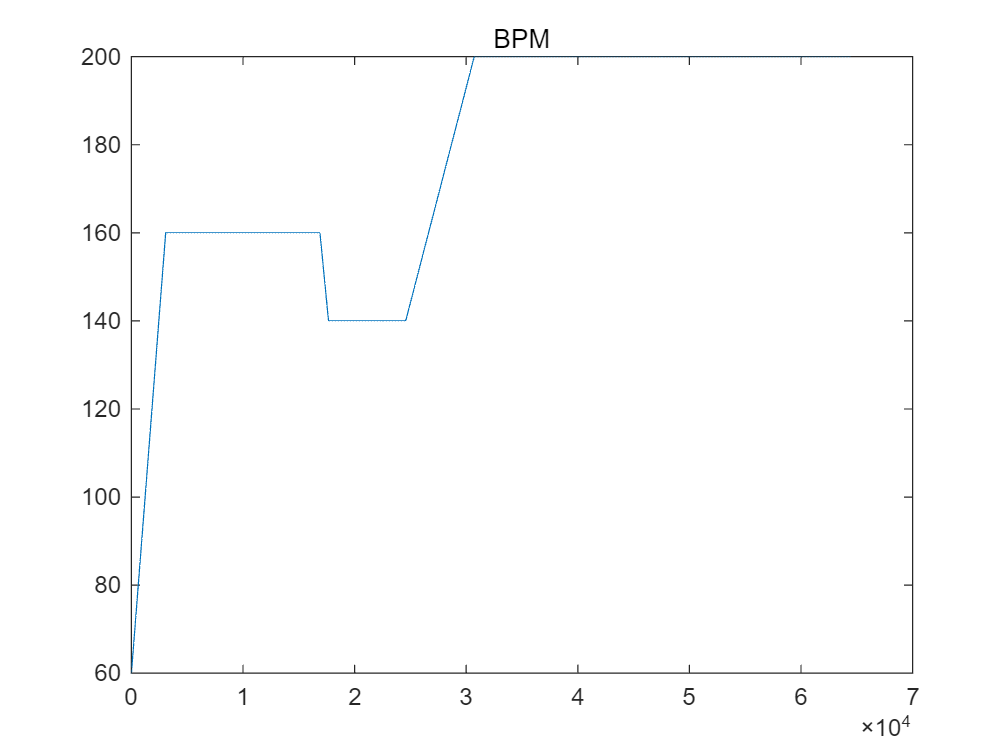

BPM=[linspace(60,160,48*8*8) linspace(160,160,48*8*8) 160*ones(1,48*8*28) linspace(160,140,48*8*2) 140*ones(1,48*8*18) linspace(140,200,48*8*16)  200*ones(1,48*8*88)];
deltatime=60/96./BPM;
ctime=cumsum(deltatime);
clf,plot(BPM),title('BPM')

With all the above preparations, we can finally write the audio to the signal. It is not a bad idea to set the total duration to 200 seconds, i.e. the signal length is 200*fs for a two-channel file.

**4. Write notes to audio**

(1.1) Write piano track to audio

s=soundTrack(Pianotrack,source.Piano,200,ctime,fs,6.2*fs,12000);

(1.2)Adjusting the Piano Volume Level

ModVolPiano=1./[0.9*ones(1,30*fs) linspace(0.9,2,48.7*fs) linspace(1.1,2.5,51*fs) 1.2*ones(1,70.3*fs)];
t=0.1*fs;
tChorus=30*fs+48.7*fs+51*fs;
t1=beat2time(200,1)*fs;t2=beat2time(200,2)*fs;T=beat2time(200,16*8)*fs

T = 1693440

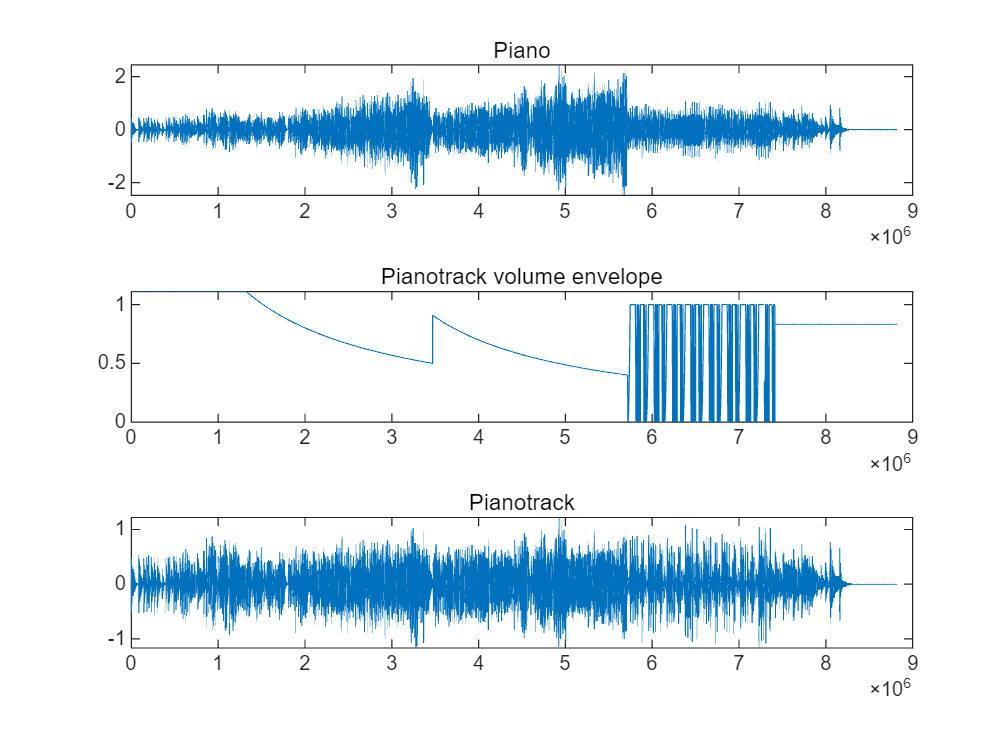

clear ModChorus
for i=1:t2
    ModChorus(i)=(i/t2)^2;
end
for i=[2*t1:7*t1 8*t1:9*t1 11*t1:14*t1]
    ModChorus(i)=1;
end
for i=[7*t1:8*t1 9*t1:11*t1 14*t1:16*t1]
    ModChorus(i)=(mod(i,t1)/t1)^2;
end
for i=[7*t1-t:7*t1 9*t1-t:9*t1 10*t1-t:10*t1 14*t1-t:14*t1 15*t1-t:15*t1]
    ModChorus(i)=(mod(i,t1)-t1)/(-t);
end
%ModChorus%=repmat(ModChorus,1,8)
[~,ind]=find(ModChorus>1);
ModChorus(ind)=0;
ModChorus=repmat(ModChorus,1,8);
ModVolPiano(tChorus+1:tChorus+T)=ModChorus;
clf,clear t1 t2 ind t
subplot(3,1,1),plot(s(1,:)),title('Piano')
subplot(3,1,2),plot(ModVolPiano),title('Pianotrack volume envelope')
sPiano=s.*ModVolPiano;
subplot(3,1,3),plot(sPiano(1,:)),title('Pianotrack')

(1.3) Adding Reverb to a Piano

effect.R1=reverberator;
effect.R1.WetDryMix=0.22;
effect.R1.HighCutFrequency=14000;
sMix=effect.R1(sPiano')';
% sound(sMix,fs)

(2.1) Write the drums to audio:

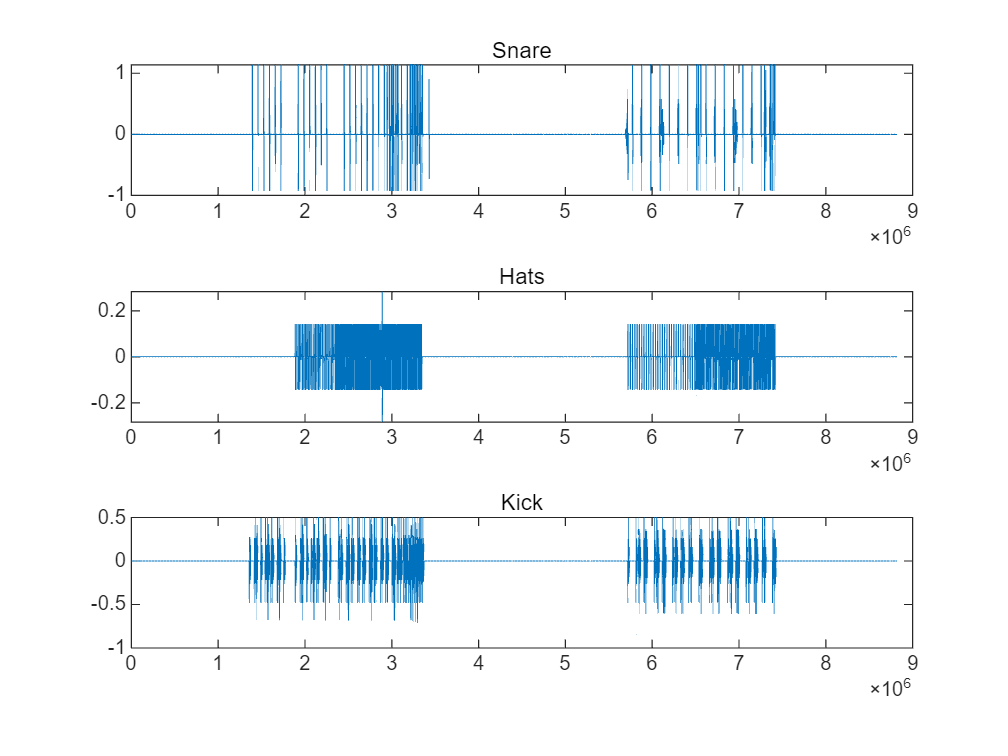

sSnare=soundTrack(Snarestrack,source.Snare,200,ctime,fs,length(source.Snare),12000);
sHats=soundTrack(Hatstrack,source.hats,200,ctime,fs,length(source.hats),12000);
sKick=soundTrack(Kicktrack,source.Kick,200,ctime,fs,length(source.Kick),12000);
clf,subplot(3,1,1),plot(sSnare(1,:)),title('Snare')
subplot(3,1,2),plot(sHats(1,:)),title('Hats')
subplot(3,1,3),plot(sKick(1,:)),title('Kick')

%sound(sSnare(:,44100*30:end),fs)
%sound(sHats:,44100*30:end),fs)
%sound(sKick(:,44100*30:end),fs)

(2.2)Mixing drum kits

sDrums=sSnare+sHats+sKick*2;
sDrumsMix=Compressor(sDrums,1,4,0.01,0.03,5,0.22)/2;
%sound(sDrumsMix(:,44100*30:end),fs)

（3）Write source.Pluck to audio:

sPluck=soundTrack(Plucktrack,source.Pluck,200,ctime,fs,length(source.Pluck{21}),12000);

clear sPluckMix
sPluckMix(1,:)=Delay(sPluck(1,:),0.5,200,3,30);
sPluckMix(2,:)=Delay(sPluck(2,:),0.5,200,3,302);
sPluckMix=sPluckMix(:,1:length(sPluck))/5;
effect.R2=reverberator;
sPluckMix=effect.R2(sPluckMix')';
sound(sPluckMix(:,44100*82:end),fs)

(4)Write source.Lead to audio:

sLead=soundTrack(Leadtrack,source.Lead,200,ctime,fs,length(source.Lead{21}),10000);

clear ModVolLead
ModVolLead=zeros(1,200*fs);
tOutro=tChorus+T;
releaseTime=6;
aa=0;bb=0.2;
ModVolLead(tChorus+1:tChorus+T)=(bb-aa).*ModChorus+aa;
for i=tOutro+1:tOutro+releaseTime*fs
ModVolLead(i)=bb-bb*(i-tOutro)/releaseTime/fs;
end
sLeadMix=sLead.*ModVolLead;
effect.R3=reverberator

effect = 包含以下字段的 struct :
                 C1: [1×1 compressor]
    Snarecompressor: [1×1 compressor]
                 R1: [1×1 reverberator]
                 R2: [1×1 reverberator]
                 R3: [1×1 reverberator]

effect.R3.Diffusion=0.7;
effect.R3.HighCutFrequency=16000;
effect.R3.WetDryMix=0.2;
sLeadMix=effect.R3(sLeadMix')';clear aa bb releaseTime 
% sound(sLeadMix(:,44100*129:end),fs)

(5)Adding effects

effect.reverbP=reverberator;;
source.reversePiano=flip(effect.reverbP(source.Piano{60}))';
%sound(source.reversePiano,fs)
sFx=zeros(2,200*fs);
sFx(:,129.81*fs-length(source.reversePiano)+1:129.81*fs)=sFx(:,129.81*fs-length(source.reversePiano)+1:129.81*fs)+source.reversePiano;

source.riser=fnote2([40 70],20,wave.wave2,@(x) 1,1 );
%sound(source.riser,fs)
sFx(:,round(129.6*fs)-length(source.riser)+1:round(129.6*fs))=sFx(:,round(129.6*fs)-length(source.riser)+1:round(129.6*fs))+repmat(source.riser,2,1)/10;

**5. All audio feeds into the bus**

%s1=smooth(sKicks);  
s1=sMix+sDrumsMix+sPluckMix+sLeadMix+sFx*2;
% sound(s1(:,44100*30:end),fs)  
% sound(s1(:,44100*60:end),fs) 
% sound(s1(:,44100*82:end),fs)
% sound(s1(:,44100*129:end),fs)  
%sound(s1,fs)

effect.L1=limiter

effect = 包含以下字段的 struct :
                 C1: [1×1 compressor]
    Snarecompressor: [1×1 compressor]
                 R1: [1×1 reverberator]
                 R2: [1×1 reverberator]
                 R3: [1×1 reverberator]
            reverbP: [1×1 reverberator]
                 L1: [1×1 limiter]

effect.L1.Threshold=-0.1;
effect.L1.KneeWidth=5;
S=effect.L1(s1*1.1);

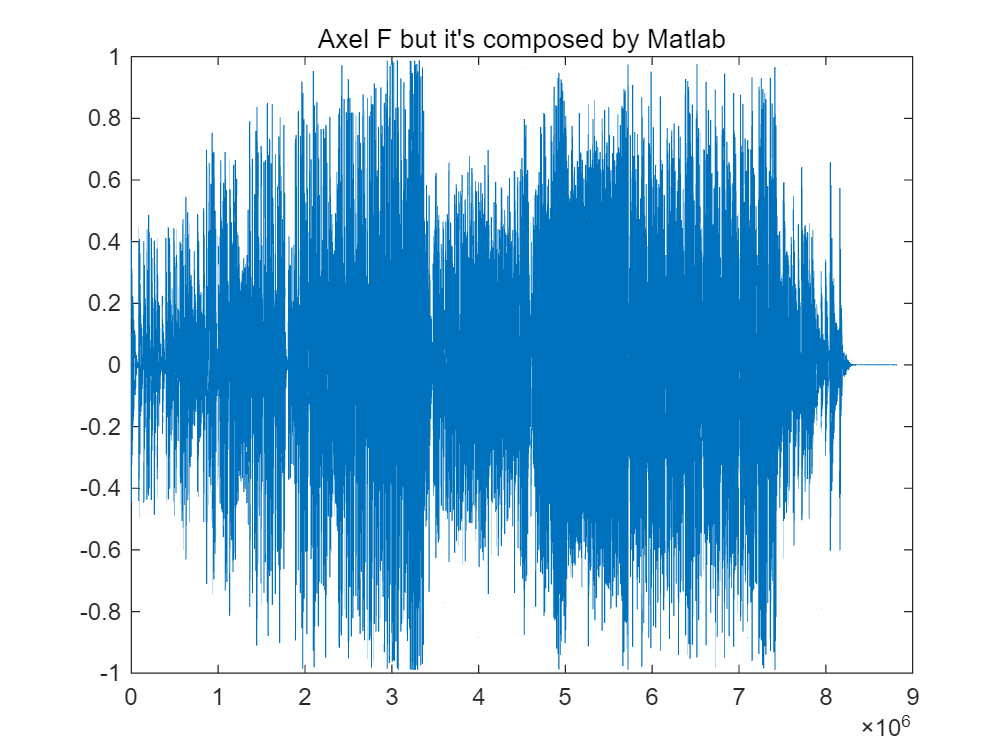

%audiowrite("Axel F but it's composed by Matlab.mp3",S',fs)
clf,plot(S(1,:)),title("Axel F but it's composed by Matlab")

The file has been saved as an MP3

sound(S,fs)

### Reference

 Mixing audio : Concepts, Practices and Tools  - Roey lzhaki